# 第3部分：图像绘制

scale = 2

scale = 2

x = 0:0.1:scale*pi;
x

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y1 = sin(x);
y2 = cos(x);

## 二维曲线绘制

### 基本函数

plot(y)

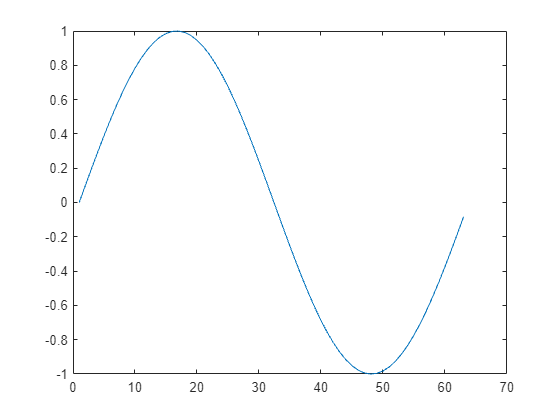

% y 为向量
plot(y1); % 纵坐标为y的值；横坐标自动为元素序号(角标+1)，此处为1~63

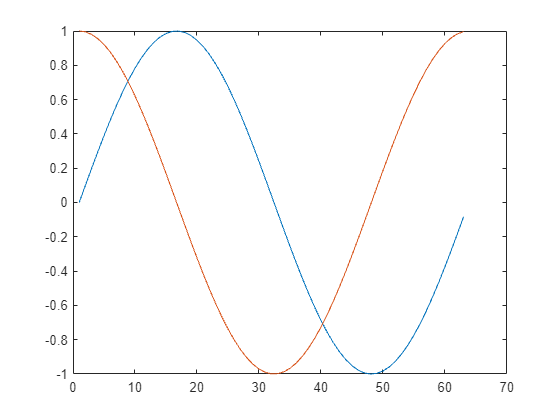

% y为矩阵
figure; % 开启新绘图窗口，下一次绘图在新窗口
y = [y1', y2']; % ' 为转置，将行向量转换为列向量
plot(y); % 当y为矩阵，按每一列画出曲线，颜色自动区分

plot(x, y)

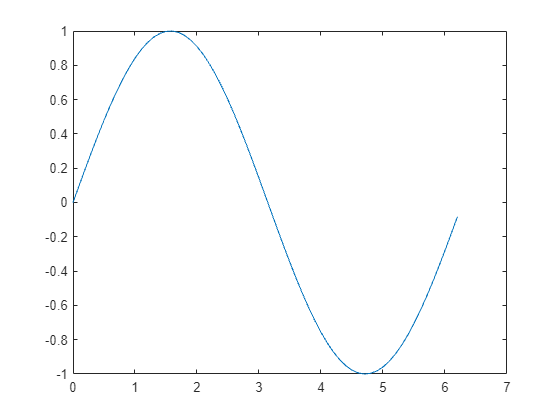

% xy为向量
plot(x, y1); % 先绘制曲线

plot(x1, y1, x2, y2...)

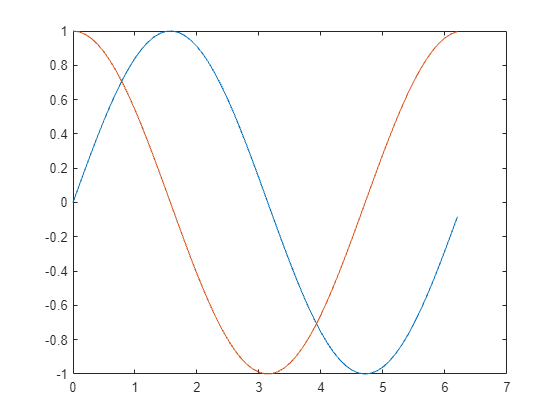

plot(x, y1, x, y2); % 在同一个窗口同一坐标轴绘制多条曲线

### 线性图形格式设置

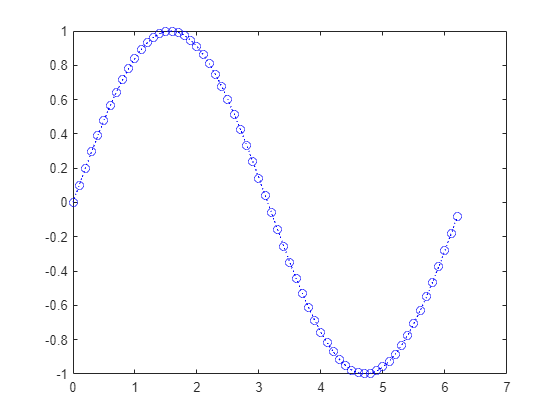

% 线形颜色数据点
% b蓝 g绿 r红 c青 m紫 y黄 k黑 w白
% -实线 :点线 --虚线 -.点画线（点线相交）
% .实点 o圆圈 x叉 +十字 *星号 s方块 d钻石 v下三角 ^上三角 <左三角 >右三角 p五角星 h六角星
plot(x, y1, 'b:o'); % 蓝色 点线 圆圈

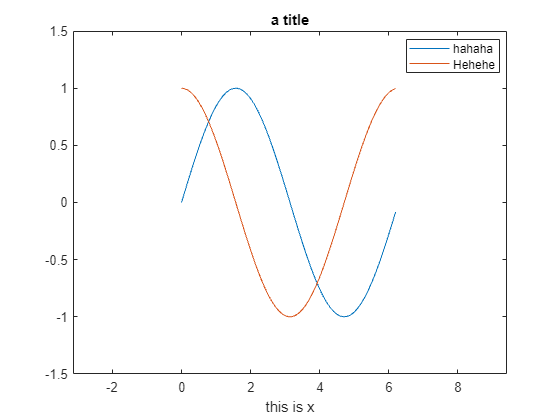

plot(x, y1, x, y2);
% 坐标轴
axis([-1*pi, 3*pi, -1.5, 1.5]); % 规定横纵坐标范围（xMin, xMax, yMin, yMax）

% 标题标签
title('a title'); % 图像标题
xlabel('this is x'); % x 轴标记，同理还有 ylabel，zlabel

% 图例设置
% 先分别给出所有例图名称。后边接选项+内容，如下。
% 'Location' 是固定选项，后跟 'best'、'northeast' 等。
% 此外还有 'Orientation'，后跟 'horizontal'、'vertical'（默认值）等。
legend('hahaha', 'Hehehe', 'location', 'best'); % str的顺序与绘图顺序一致

图形保持

plot(x, y1);
hold on; % 在原有窗口y1曲线上增加绘制下一个图形
plot(x, y2); % y2在同一窗口内被绘制
hold off;

分割绘制

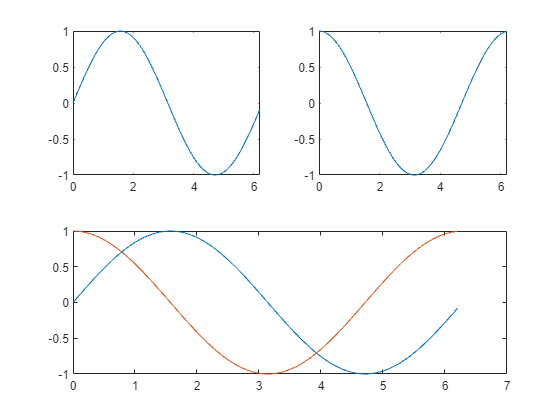

subplot(2, 2, 1); % 分割成2x2区域，在第一块区域绘制下一个图形
plot(x, y1); % y1被绘制在4块区域的第一块
subplot(2, 2, 2); % 分割方法相同，区域改变
plot(x, y2); % y2在第二块区域
subplot(2,2,[3,4]); % 两块一起用
plot(x, y1, x, y2); % y2在第二块区域

## *二维特殊图形绘制

figure; % 开启新绘图窗口，下一次绘图在新窗口

柱状图

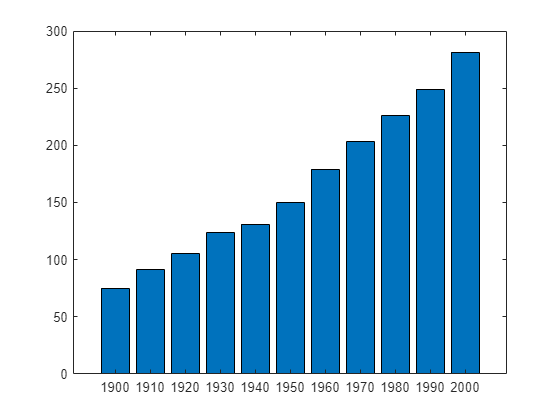

x = 1900:10:2000;
y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
% width宽度默认0.8，超过1各条会重叠;
% 参数有grouped分组式，stacked堆栈式; 默认grouped
% bar垂直柱状图,barh水平柱状图,bar3三维柱状图,barh3水平三维柱状图(三维多一个参数detached, 且为默认)
bar(x,y); % x横坐标向量，m个元素; y为向量时，每个x画一竖条共m条，矩阵mxn时，每个x画n条

饼形图

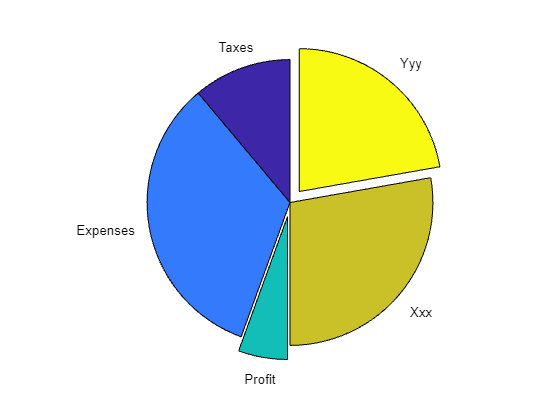

X = [1 3 0.5 2.5 2];
explode = [0 0 1 0 1]; % 是否往外挪一点点出去（explode向量与x同长度，为1表示该元素被分离突出显示，默认全0不分离）
labels = {'Taxes','Expenses','Profit', 'Xxx', 'Yyy'}; % 默认显示百分比，这样写会直接覆盖掉百分比
pie(X,explode, labels) % x为向量显示每个元素占总和百分比, 为矩阵显示每个元素占所有总和百分比

直方图

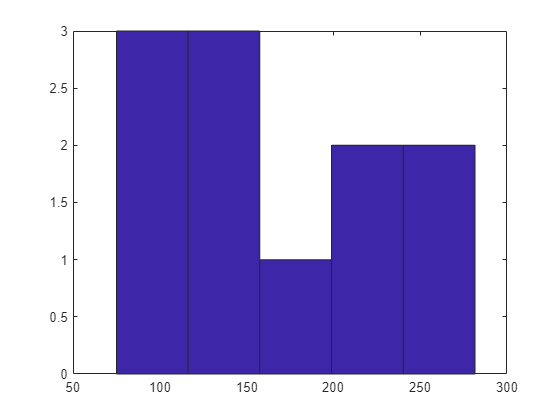

hist(y, 5); % y为向量，把横坐标分为n段绘制

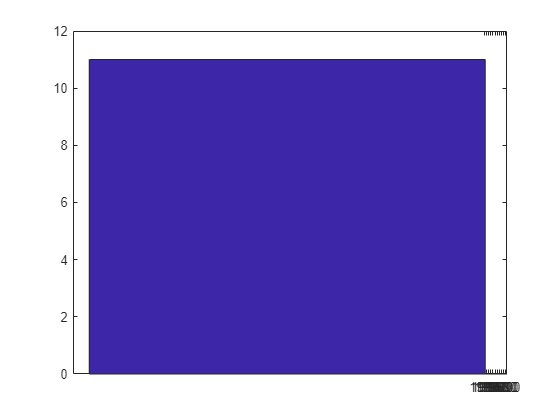

hist(y, x); % x为向量，用于指定每段中间值, 若取 N = hist(y, x), N为每段元素个数

离散数据图

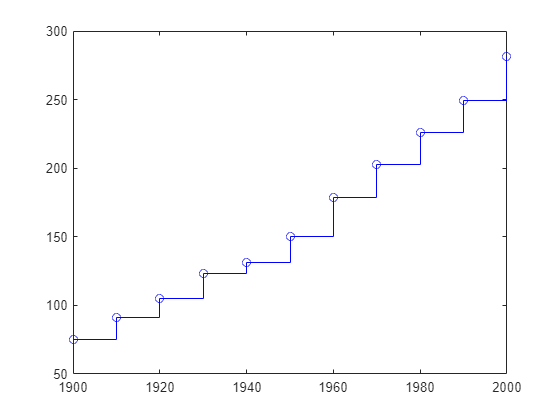

stairs(x, y, 'b-o'); % 阶梯图，参数同plot

火柴杆图

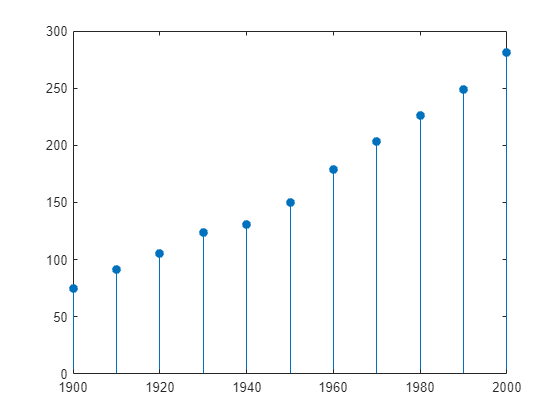

stem(x, y, 'fill'); % 参数fill是填充火柴杆，或定义线形

蜡烛图

% candle(HI, LO, CL, OP); % HI为最高价格向量,LO为最低价格向量,CL为收盘价格向量,OP为开盘价格向量

向量图

% compass(u, v, 'b-o'); % 罗盘图横坐标u纵坐标v
% compass(Z, 'b-o'); % 罗盘图复向量Z
% feather(u, v, 'b-o'); % 羽毛图横坐标u纵坐标v
% feather(Z, 'b-o'); % 羽毛图复向量Z
% quiver(x, y, u, v); % 以(x, y)为起点(u, v)为终点向量场图

极坐标图

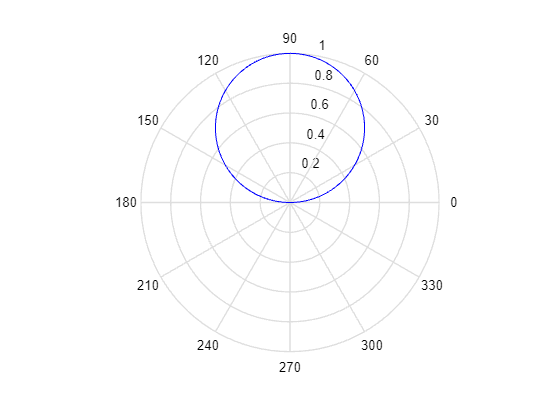

% polar(theta, rho, 'b-o'); % 极角theta, 半径rho
theta = -pi:0.01:pi;
rho = sin(theta);
polar(theta, rho, 'b')

对数坐标图

% semilogx(x1, y1, 'b-o'); % 把x轴对数刻度表示, semilogy是y轴对数刻度表示，loglog是两个坐标都用对数表示

双纵坐标

% plotyy(x1, y1, x2, y2, 'fun1', 'fun2'); % fun规定了两条条线的绘制方式，如plot,semilogx,semilogy,loglog,stem等

函数绘图

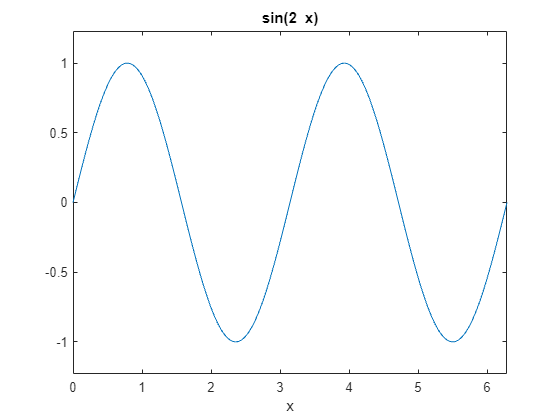

f = 'sin(2*x)';
ezplot(f, [0, 2*pi]); % 绘制f并规定横坐标范围，也有[xmin, xmax, ymin, ymax]

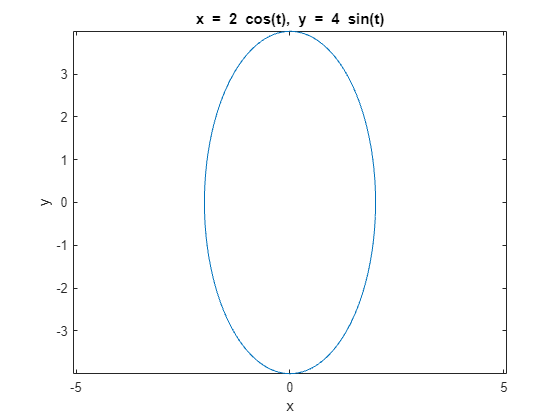

x = '2*cos(t)';
y = '4*sin(t)';
ezplot(x, y); % 绘制x(t),y(t)在[0, 2*pi]图像, 也可以在最后用[tmin, tmax]规定t的范围

## 三维曲线曲面绘制

三维曲线

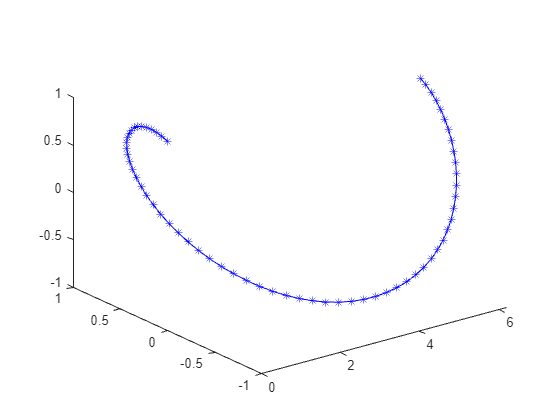

x = 0:0.1:2*pi;
y = sin(x);
z = cos(x);
plot3(x, y, z, 'b-*');

三维曲面

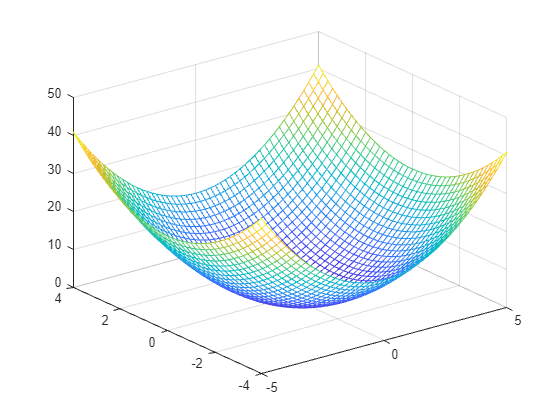

%三维网格
x = -5:0.2:5; % 规定了x轴采样点，也规定了x轴范围
y = -4:0.2:4; % 规定了y轴采样点，也规定了y轴范围
[X, Y] = meshgrid(x, y); % 得到了xoy面网格点
Z = X.^2+Y.^2;
mesh(X, Y, Z) % XY是meshgrid得到的网格点，Z是网格顶点，c是用色矩阵可省略

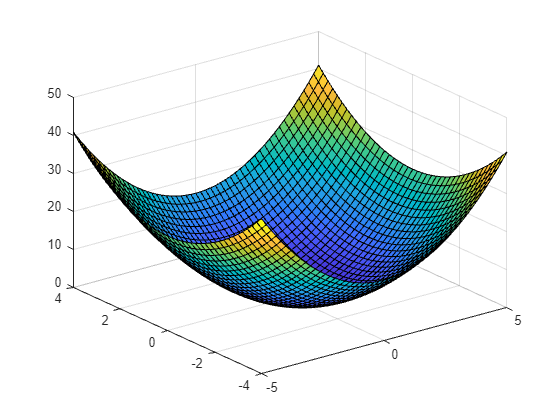

%三维表面图
x = -5:0.2:5;
y = -4:0.2:4;
[X, Y] = meshgrid(x, y);
Z = X.^2+Y.^2; % 以上部分同上
surf(X, Y, Z) % 与上一个类似